# **细胞计数器V2**

### **背景：在细胞生物学的实验中，往往需要对活细胞进行观察与计数，对细胞生长情况进行估计或得到相应的实验结果，从而调整细胞密度，指导实验进度。**

### **思路：灰度化 -> 提取边缘 -> 二值化 -> 腐蚀膨胀 -> 统计连通分量**

### **问题1****：数量变化区间大，同一个培养孔会出现密度相差很大的视野**

### **问题****2****：细胞粘连情况下计数的准确度（需要制定计数标准）**

### **问题****3****：细胞不规则形状的数值计算难点**

# **都解决了！！！**

## 项目分工：

张淳皓：项目框架构建与项目整合

申若曦：项目调研与滑动组件部分设计

黄土：项目调研与二值化部分设计

徐述：项目调研与保存文件部分设计

## 1、打开一张图片

filename = uigetfile({'*.jpg'; '*.bmp'; '*.tif'}, '选择一张图片')

filename = '微信图片_20210408180412.png'

filepath = "D:\\workspace\\Matlab\\细胞计数器\\" + filename;
rgbImg = imread(filepath);

% 调整图片尺寸
[w, h, ~] = size(rgbImg)

w = 293

h = 358

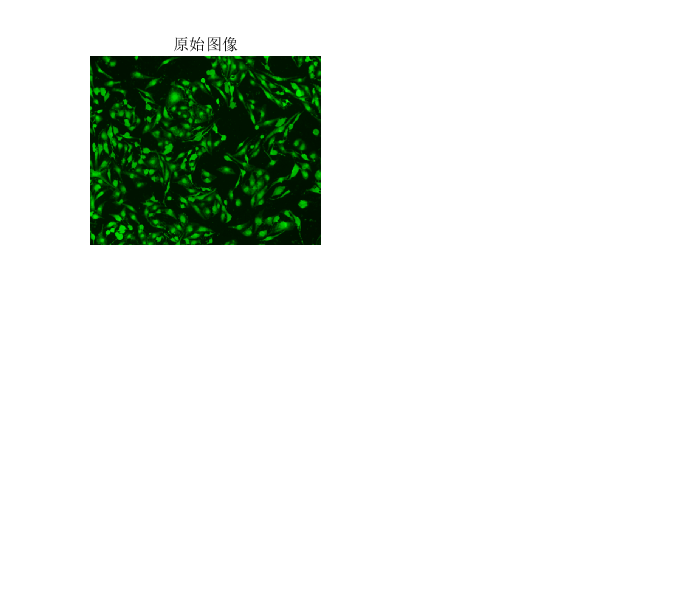

rgbImg = imresize(rgbImg,[500, round(h * (500 / w))]);

% 显示
imshow(rgbImg);
title('原始图像');

## 2、USM锐化提取边缘

首先，将原图像转化为灰度图像

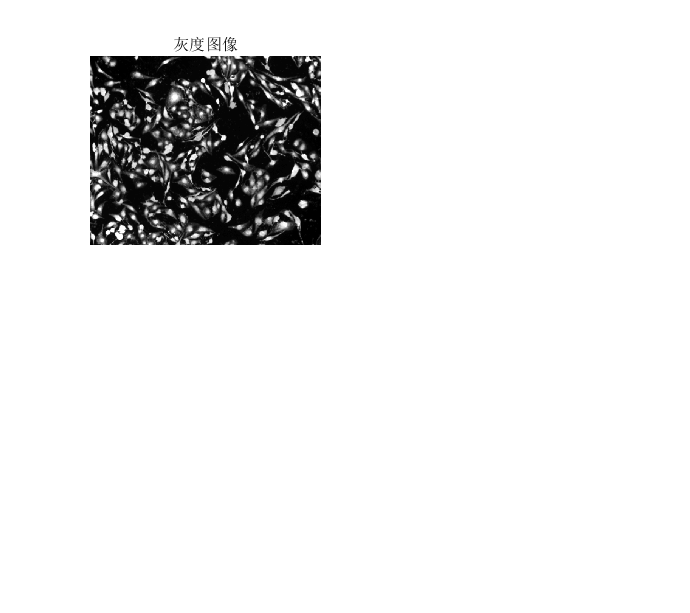

% 灰度化
grayImg = rgb2gray(rgbImg);
% 自动调整效果
grayImg = imadjust(grayImg);
% 显示
imshow(grayImg);
title('灰度图像');

然后，获取高斯模糊图像

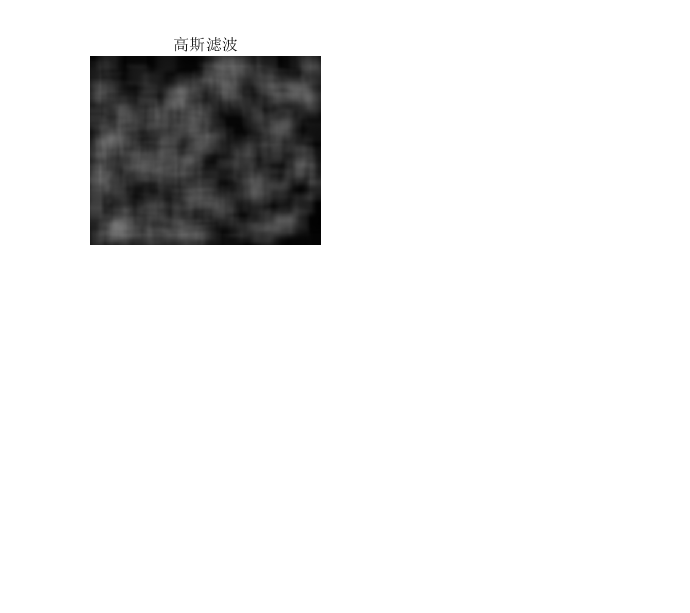

% 创建二位滤波器
% TODO: 这里加两个数值滑块，分别控制模糊半径和sigma
gaussRadius = 55;   
gaussSigma = 95;
gaussH = fspecial('gaussian', [gaussRadius, gaussRadius], gaussSigma);

% 高斯滤波
gaussImg = imfilter(grayImg, gaussH);

% 显示
imshow(gaussImg);
title('高斯滤波');

由原图像和高斯滤波后的图像相减，得到边缘图像。

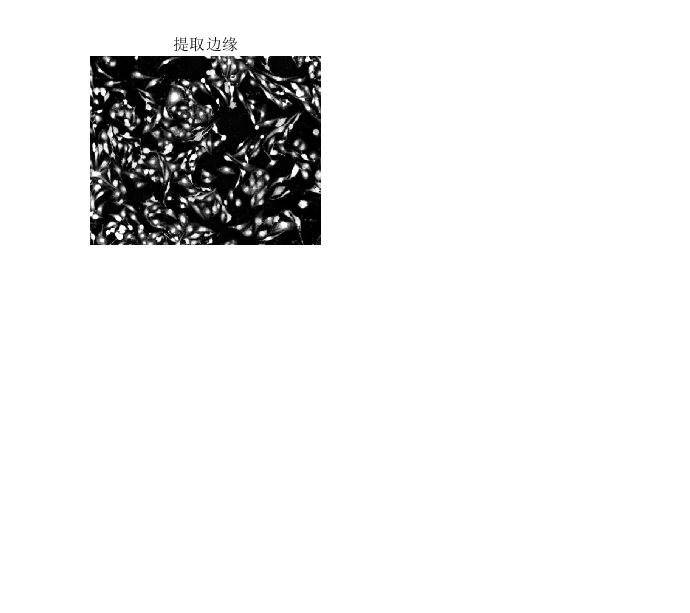

% USM锐化的权重
% TODO: 这里加一个0到1的数值滑块，选择权重
weight = 0.1;

% 加权相减
usmImg = uint8((double(grayImg)-weight.*double(gaussImg))./(1-weight));

% 显示
imshow(usmImg);
title('提取边缘');

将提取的边缘图像二值化，提高对比度，并取反（使前景亮于背景）

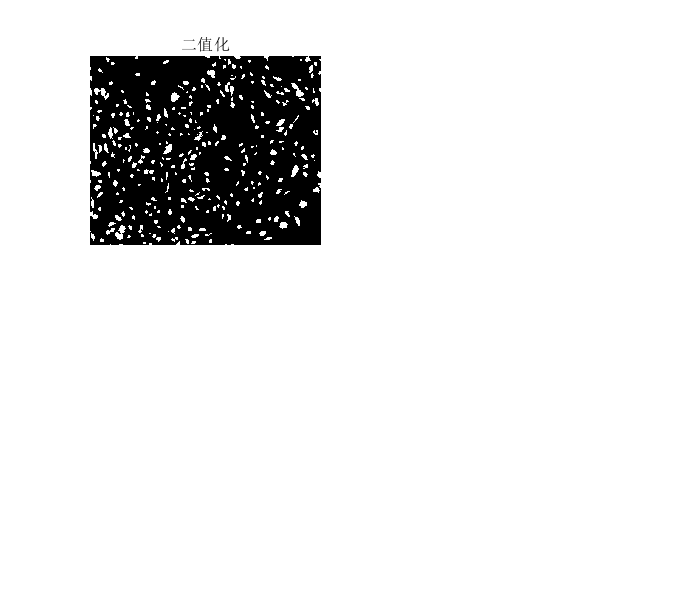

% 二值化，这里用的是自适应二值化
% 可能不能使用这个函数，他把数值都转成布尔类型了。应该自己写一个底层的二值化函数
% TODO: 加一个数值滑块，使可以控制二值化的阈值
chooseAlg = 'manual';
levelManual = 185;
switch(chooseAlg)
    % 使用OTUS算法计算最佳的阈值
    case 'ostu'
        level=graythresh1(usmImg);
        disp("阈值为：" + num2str(level));
    % 手动调节阈值
    case 'manual'
        level = levelManual;
end
bwImg = ImBinary(usmImg,level);

% 取反
% 若前景为暗，则需要反色
% TODO: 这里加一个控件，选择是否反色
doInvert = 0;
if(doInvert)
    bwImg = ~bwImg;
end

% 显示
imshow(bwImg);
title('二值化');

## 3、腐蚀膨胀

加入腐蚀膨胀，可以分离、填充不完美的局部

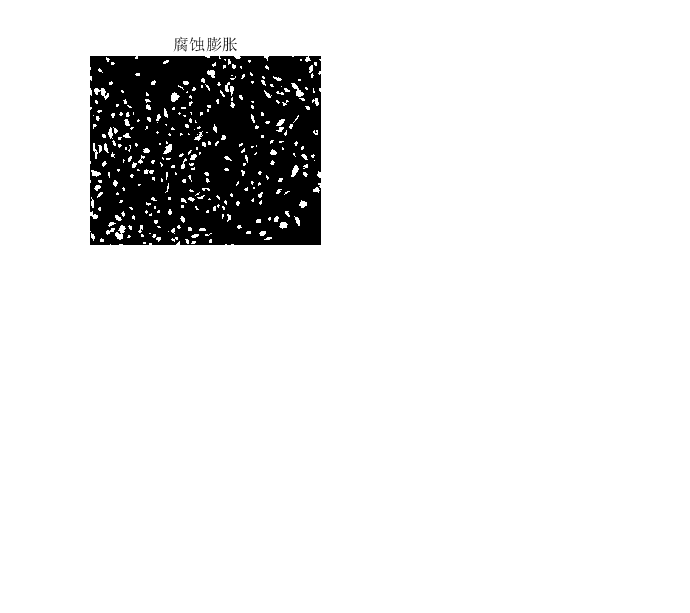

% TODO: 加一个填充功能
% 使用正方形掩膜进行腐蚀和膨胀
% 可以调整掩膜半径、腐蚀次数、膨胀次数

% 掩膜半径，根据细胞核大小进行调整
radius = 3;
% 腐蚀次数，数值越大效果越强
valueDilate = 3;
% 膨胀次数，数值越大效果越强
valueErode = 1;

% 调用腐蚀膨胀函数
bwImgPro = imorph(bwImg, radius, valueDilate, valueErode);

% 显示   
imshow(bwImgPro);
title('腐蚀膨胀');

## 4、统计连通分量个数得到细胞数目

% 标记连通区域，使用4连通，返回标记后的图像
labeledImg = bwlabel(bwImgPro, 4);

% 得到各个连通区域的属性，返回结构体数组
props = regionprops(labeledImg, 'Area');

% 滤掉像素点太少的区域
% TODO: 这里加一个数值滑块，控制要忽略的连通分量的像素数阈值
% 要选择的连通分量的像素下限
pixThLow = 0;
% 要选择的连通分量的像素上限
pixThHigh = 1000;
fltedImg = ismember(labeledImg, find([props.Area] >= pixThLow & [props.Area] <= pixThHigh));
% fltedImg = ismember(labeledImg, find([props.Area] <= pixThHigh));

% 对过滤后的图像重新标注连通区域
labeledImg2 = bwlabel(fltedImg, 4);
propsFlted = regionprops(labeledImg2, 'Area', 'BoundingBox');

% 获得连通分量个数以及各个连通分量的边界框
areas = [propsFlted.Area];  % 一个行向量，列数即为连通分量个数
rects = cat(1, propsFlted.BoundingBox);   % 边界框，用于细胞标注
[~, numConnected] = size(areas);    % 获得连通分量个数
numConnected    % 展示数量

numConnected = 367

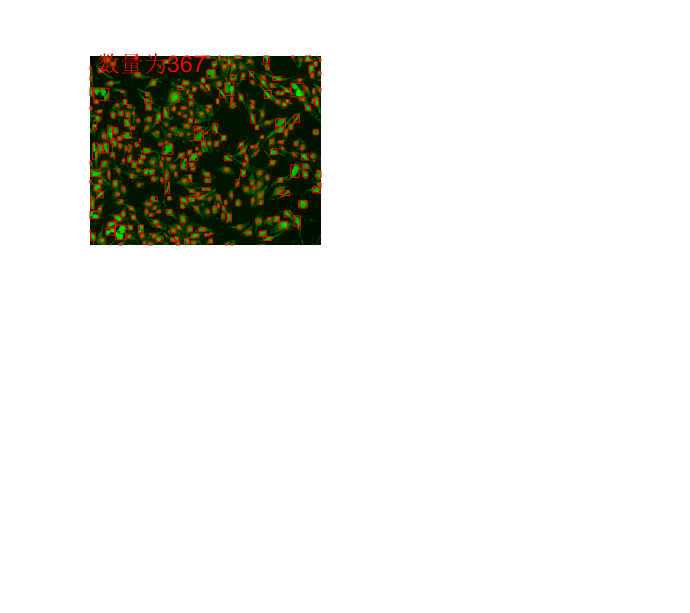


% 在原图像中进行目标标注
% 先显示原图像
imshow(rgbImg, 'InitialMagnification', 100); 
% 标记矩形框
for i = 1 : size(rects, 1)
    rectangle('position', rects(i, :), 'EdgeColor', 'r');
end
% 标记文本
dispText = "数量为" + num2str(numConnected);
text(20, 20, dispText, 'FontSize', 14, 'Color', 'red');

% 保存图像
imgName = "result" + '.jpg';
saveas(gcf, imgName);

### Func：手动二值化函数

function imAfter=ImBinary(imBefore, threshhold)
    imAfter = imBefore;
    for i=1:size(imAfter, 1)
        for j=1:size(imAfter, 2)
            if imAfter(i, j) >= threshhold
                imAfter(i, j) = 255;
            else
                imAfter(i, j) = 0;
            end
        end
    end
end

### Func：膨胀和腐蚀函数

function bwImgAfter = imorph(bw, radius, valueErode, valueDilate)
    bwImgAfter = bw;
% 使用正方形掩膜，三个参数分别为掩膜半径、膨胀次数（系数）、腐蚀次数（系数）
    % 初始化一个掩膜
    SE = strel('square', radius);

    % 膨胀
    if valueDilate>0
        for i=1:valueDilate
            bwImgAfter = imdilate(bwImgAfter, SE);
        end
    end
    
    % 腐蚀
    if valueErode>0
        for j=1:valueErode
            bwImgAfter = imerode(bwImgAfter, SE);            
        end
    end    
    
end

### Func：使用OTUS算法计算最佳阈值

function level = graythresh1(usmImg)
    level=0;
    I=usmImg;  %变为双精度，即0-1
    subplot(221);imhist(I);            %显示灰度直方图
    [M,N]=size(I);                     %得到图像行列像素
    number_all=M*N;                    %总像素值
    hui_all=0;                         %预设图像总灰度值为0
    ICV_t=0;                           %预设最大方差为0
    %得到图像总灰度值
    for i=1:M
        for j=1:N
            hui_all=hui_all+I(i,j);
        end
    end
    all_ave=hui_all*255/number_all;   %图像灰度值的总平均值
     
     
    %t为某个阈值，把原图像分为A部分（每个像素值>=t）与B部分（每个像素值<t）
    for t=0:255                       %不断试探最优t值
        hui_A=0;                      %不断重置A部分总灰度值
        hui_B=0;                      %不断重置B部分总灰度值
        number_A=0;                   %不断重置A部分总像素
        number_B=0;                   %不断重置B部分总像素
        for i=1:M                     %遍历原图像每个像素的灰度值
            for j=1:N
                if (I(i,j)*255>=t)    %分割出灰度值>=t的像素
                    number_A=number_A+1;  %得到A部分总像素
                    hui_A=hui_A+I(i,j);   %得到A部分总灰度值
                elseif (I(i,j)*255<t) %分割出灰度值<t的像素
                    number_B=number_B+1;  %得到B部分总像素
                    hui_B=hui_B+I(i,j);   %得到B部分总灰度值
                end
            end
        end
        PA=number_A/number_all;            %得到A部分像素总数与图像总像素的比列
        PB=number_B/number_all;            %得到B部分像素总数与图像总像素的比列
        A_ave=hui_A*255/number_A;          %得到A部分总灰度值与A部分总像素的比例
        B_ave=hui_B*255/number_B;          %得到B部分总灰度值与B部分总像素的比例
        ICV=PA*((A_ave-all_ave)^2)+PB*((B_ave-all_ave)^2);  %Otsu算法
        if (ICV>ICV_t)                     %不断判断，得到最大方差
            ICV_t=ICV;
            k=t;                           %得到最大方差的最优阈值
        level=k;
        end
    end    
end